clear; close all; clc;
x=0.04;
y=0.04;
nx=25; % Grid size in x
ny=25; % grid size in y
dx=x/nx; % step size in x
dy=y/ny;% step size in y
dt=0.25; % time step size
h=400; % thermal coeficient of convection
k=61; % thermal conductivity
alpha=0.000016; % thermal diffusivity
To=100;  % initial temperature
Tinf=25; % ambient temperature
imax=nx+1;
jmax=ny+1;
T(1:imax,1:jmax)=To;
rx=(alpha*dt)/(dx*dx);
ry=(alpha*dt)/(dy*dy);

%%%%%%%%%%%%%%%%%% ADI Method %%%%%%%%%%%%%%%%%%%%%%%%%%%
for t=dt:dt:60

    a(1,1)=1;
    a(imax,1)=0;
    b(1,1)=0;
    b(imax,1)= -k/dx;
    d(1,1)= -1;
    d(imax,1)=(k/dx)+h;
    c(1,1)=0;
    c(imax,1)=h*Tinf;
    %implicit in x
    for j=2:1:jmax-1
        for i=2:1:imax-1
            a(i,1)=-rx/2;
            b(i,1)=-rx/2;
            d(i,1)=1+rx;
            c(i,1)=T(j,i)+(ry*(T(j+1,i)-2*T(j,i)+T(j-1,i))/2);
        end
        Tnew(j,:)=(TDMA(b,d,a,c,imax));
    end


    Tnew(1,:)=Tnew(2,:);
    Tnew(jmax,:)=((k*Tnew(jmax-1,:)/dy+h*Tinf)/((k/dy)+h));
    T=Tnew;
        a(1,1)=1;
        a(jmax,1)=0;
        b(1,1)=0;
        b(jmax,1)= -k/dy;
        d(1,1)= -1;
        d(jmax,1)=(k/dy)+h;
        c(1,1)=0;
        c(jmax,1)=h*Tinf;
     % implicit in y
    for i=2:1:imax-1
        for j=2:1:jmax-1
            a(j,1)=-ry/2;
            b(j,1)=-ry/2;
            d(j,1)=1+ry;
            c(j,1)=T(j,i)+(rx*(T(j,i+1)-2*T(j,i)+T(j,i-1))/2);
        end
        Tnew(:,i)=(TDMA(b,d,a,c,jmax));
    end
    Tnew(:,1)=Tnew(:,2);
    Tnew(:,imax)=((k*Tnew(:,imax-1)/dx+h*Tinf)/((k/dx)+h));
    T=Tnew;
end
% Temperature matrix
disp(T)

   84.8595   84.8595   84.8355   84.7877   84.7159   84.6203   84.5008   84.3575   84.1905   83.9998   83.7854   83.5475   83.2862   83.0015   82.6935   82.3624   82.0083   81.6313   81.2315   80.8092   80.3644   79.8974   79.4083   78.8974   78.3647   77.8107
   84.8595   84.8595   84.8355   84.7877   84.7159   84.6203   84.5008   84.3575   84.1905   83.9998   83.7854   83.5475   83.2862   83.0015   82.6935   82.3624   82.0083   81.6313   81.2315   80.8092   80.3644   79.8974   79.4083   78.8974   78.3647   77.8107
   84.8355   84.8355   84.8116   84.7638   84.6921   84.5965   84.4770   84.3338   84.1668   83.9762   83.7619   83.5241   83.2629   82.9783   82.6705   82.3395   81.9855   81.6086   81.2090   80.7869   80.3423   79.8755   79.3866   78.8758   78.3434   77.7896
   84.7877   84.7877   84.7638   84.7160   84.6443   84.5488   84.4295   84.2864   84.1195   83.9290   83.7150   83.4773   83.2163   82.9319   82.6243   82.2936   81.9399   81.5634   81.1641   80.7423   80.2980   79.8

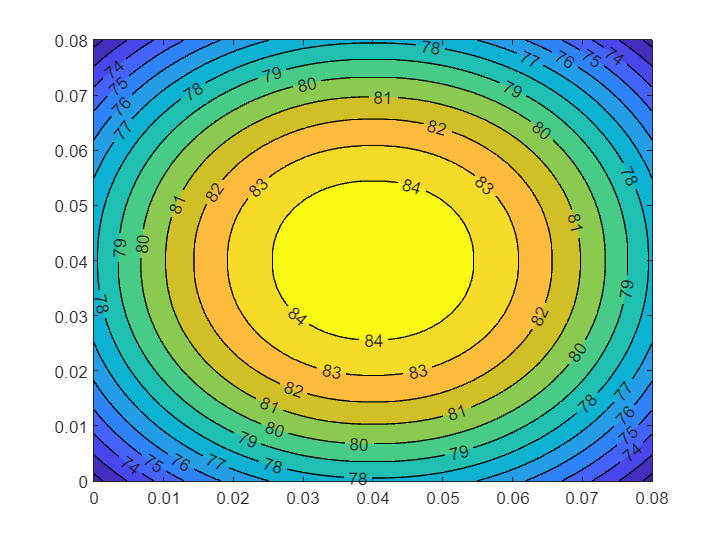

%%%% heat contour %%%%%%%
[X,Y]=meshgrid(0:dx:(x*2),0:dy:(2*y));
Tplot=[flip(flip(Tnew,2)), flip(Tnew,1); flip(Tnew,2), Tnew];
Tplot(ny+1,:)=[]; Tplot(:,nx+1)=[];
contourf(X,Y,Tplot,Tinf:To,'ShowText','on');

function sol = TDMA(b,d,a,c,n)
    g(1)=d(1); N(1)=c(1);
    for M=2:n
        g(M)=d(M)-b(M)*a(M-1)/g(M-1);
        N(M)=c(M)-b(M)*N(M-1)/g(M-1);
    end
    sol(n)=N(n)/g(n);
    for M=n-1:-1:1
    sol(M)=(N(M)-a(M)*sol(M+1))/g(M);
    end
end